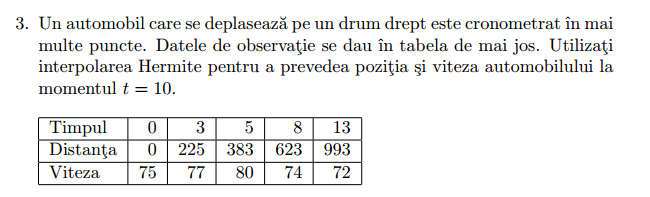


$$v = \frac{d}{\Delta{t}} \frac{d}{d\Delta{t}}$$


Reconstruim vectorul de noduri dublate pentru a calcula pozitia folosindu-ne de rezultatul interpolarii. Avand deja derivatele, stiind ca **viteza este prima derivata a distantei cu respect la timp**, ne este usor sa calcula in sens invers pentru a determina distanta.


$$\[
P'(t)
= \sum_{j=2}^{2n} Q_{j,j}\,\frac{d}{dt}\Bigl[\prod_{k=1}^{j-1}(t - z_k)\Bigr]
= \sum_{j=2}^{2n} Q_{j,j}
  \sum_{r=1}^{\,j-1}
    \prod_{{k=1, k \neq r}}^{j-1}(t - z_k).
\]
$$


t = [0 3 5 8 13];
d = [0 225 383 623 993];
v = [75 77 80 74 72];

tq = 10;
[dist10, Q] = HermitePowell(t, d, v, tq);

n = numel(t); m = 2*n;
z = zeros(1,m);
for i = 1:n
    z(2*i-1) = t(i);
    z(2*i)   = t(i);
end

vel10 = 0;
for j = 2:m
    a = Q(j,j);
    % derivative of prod_{k=1..j-1}(tq - z(k)) is
    % sum_{r=1..j-1} [ prod_{k!=r}(tq - z(k)) ]
    derTerm = 0;
    for r = 1:(j-1)
        p = 1;
        for k = 1:(j-1)
            if k==r 
                continue; 
            end
            p = p*(tq - z(k));
        end
        derTerm = derTerm + p;
    end
    vel10 = vel10 + a * derTerm;
end

fprintf('At t = %g:\n', tq);

At t = 10:


fprintf('  Predicted position = %.4f\n', dist10);

  Predicted position = 742.5028


fprintf('  Predicted velocity = %.4f\n', vel10);

  Predicted speed = 48.3817
